N_Estimate = 1024

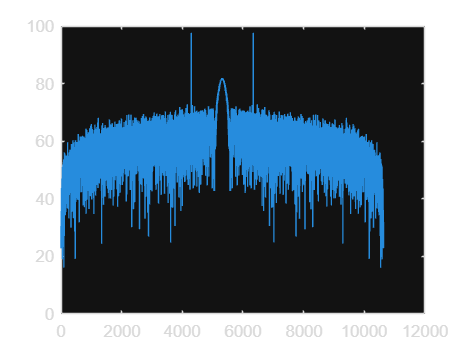

N_newEstimate = 1024

N_bestEstimate = 1024

clear all;

s.N = 1024;
s.Fs = 240e6;
s.Ng = 32;
s.Midx = 4;
s.type = "QAM";
s.SNRdB = nan();
s.Fsr = s.Fs;

s.Nsym = 300;
s.Nsfd = 300;

s.beta = 0;
s.Fc = getClosestFch(11.775e9);
s.Fcr = s.Fc;
s.Tdur = 1/750;
s.tau = 0;
s.gutter = 1;
if(s.gutter == 1)
    Nd = s.N - 4;
else
    Nd = s.N;
end

x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;

% str = genStrlkOFDM(s);
% % str = str(1:2113);
% y = autocorr(real(str));
% % y = [y(1:length(str) - 1);y(length(str) + 1:end)];
% t = 1:length(y);
% plot(t,mag2db(abs(y)));


% Frames = 5;
% str = genStrlkFrame(s);
% 
% x = randi([0 s.Midx-1],Nd,s.Nsym);
% s.data = x;
% 
% for ii=1:(Frames - 1)
%     str = [str;genStrlkFrame(s)];
% end
% 
% ind = [genPss();genSss()];
% 
% result = xcorr(ind , str);
% t = 1:length(result);
% plot(t , result);


% s.Nsym = 1000;
% x = randi([0 s.Midx-1],Nd,s.Nsym);
% s.data = x;
% str1 = genOFDM(s);
% 
% vec = xcorr(str1,str1);
% [val1 , idx1] = max(vec);
% vec(idx1) = 0;
% [val2 , idx2] = max(vec);
% secondLobeIdx = abs(idx2 - idx1)

s.Nsym = 300;
x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;
str1 = genOFDM(s);

% vec = zeros(2*length(str1)-1,1);
% for i = 1:10
%     x = randi([0 s.Midx-1],Nd,s.Nsym);
%     s.data = x;
%     str1 = genOFDM(s);
%     vec = vec + xcorr(str1,str1);
% end

input = 0;
for i = 1:10
    x = randi([0 s.Midx-1],Nd,s.Nsym);
    s.data = x;
    str1 = genOFDM(s);
    input = [input ; str1];
end
input = input(2:end);


N_Est()




str1corr = zeros(length(str1),1);
for i = 1:10
    x = randi([0 s.Midx-1],Nd,s.Nsym);
    s.data = x;
    str1 = genOFDM(s);
    str1shifted = circshift(str1,N_Estimate);
    str1temp = zeros(length(str1),1);
    for ii = 1:length(str1)
        str1temp(ii) = conj(str1(ii))*str1shifted(ii);
    end
    str1corr = str1corr + str1temp;
end
m = mean(str1corr);
str1corr = str1corr - m;
veccorr = xcorr(str1corr,str1corr);
[val3 , idx3] = max(veccorr);
veccorr(idx3) = 0;
[val4 , idx4] = max(veccorr);
Ng_Estimate = abs(idx4 - idx3) - N_Estimate

t = 1:length(veccorr);
plot(t,abs(veccorr));

% vecfft = ifft(vec);
% [fftval1 , fftidx1] = max(vecfft);
% fftSecondLobeIdx = fftidx1
% 
% t = 1:length(vec);
% plot(t,mag2db(abs(vec)));
% 
% t2 = 1:length(vecfft);
% plot(t2,mag2db(abs(vecfft)));





% corel = 1:100;
% out = zeros(length(vec2),1);
% for i = 1:length(vec2)
%     temp = 0;
%     vecvec = circshift(vec2,i);
%     for j = 1:length(corel)
%         temp = temp + vecvec(j)*corel(j);
%     end
%     out(i) = temp;
% end
% 
% out = conv(vec2,corel);

% vec2mod = xcorr(vec2,vec2);
% [valvec2 , idxvec2] = max(vec2mod);
% vec2mod(idxvec2) = 0;
% [val2vec2 , idx2vec2] = max(vec2mod);
% secondLobeIdx2 = abs(idxvec2 - idx2vec2)
% t2 = 1:length(out);
% plot(t2,mag2db(abs(out)));





% x = randi([-5 5],300*1024,1);
% y = reshape(x,1024,[]);
% cp = 32;
% z = reshape([y(end - cp:end,:);y],[],1);
% vec = xcorr(z,z);
% vec = [vec(1:length(z) - 1);vec(length(z) + 1:end)];
% t = 1:length(vec);
% plot(t,vec);

% t = 1:0.1:1e6;
% y = randi([-4 4],length(t)-1000,1);
% y = [randi([-100 100],1000,1);y];
% plot(t,y);

